## 1.

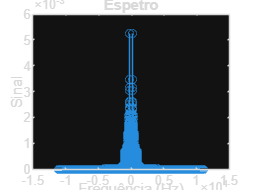

file = sprintf('Guitar03.mat');
load(file);

[X,f] = espetro(x,1/fa);

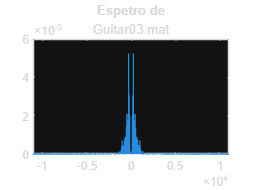

plot(f,abs(X)/length(X));
title('Espetro de', file);

## 2.

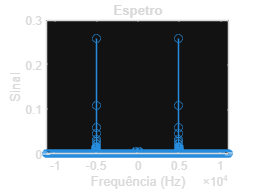

teta = 2*pi*(5e3/fa);
xr=x + 0.6*cos(teta*(0:length(x)-1)'+0.1*pi);

[xr,f] = espetro(xr,1/fa);

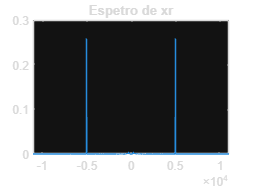

plot(f,abs(xr)/length(xr));
title('Espetro de xr');

## 3.

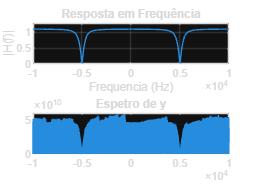

R = 0.9;
num = [1 -2*cos(teta) 1];
den = [1 -2*R*cos(teta) R^2];

figure;
subplot(2,1,1);
[H,f] = respfreq(num, den, fa);
axis([-1e4 1e4 0 1.3]);

subplot(2,1,2);
y = filter(num,den,xr);
[Y, f1] = espetro(y,1/fa);
plot(f1,abs(Y)*length(Y));
title('Espetro de y');
axis([-1e4 1e4 0 6e10]);


%É 1 em todas as frequências menos nos pontos calculados na b

4.

    b)

load('Guitar03.mat');
fa

fa = 22050

soundsc(x,fa);
a = 0.9;
distance = 17;
speed = 340;
atraso = distance/speed;
D = round(atraso*fa);
fprintf('Valor de D = %d', D);

Valor de D = 1103

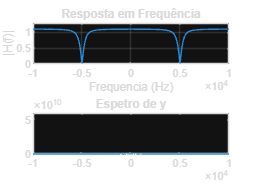


num = [1 zeros(1, D-1) a]; % 1 + az^-D
den = 1;

y  = filter(num,den,x);
soundsc(y,fa);
[Y, f1] = espetro(y,1/fa);
plot(f1,abs(Y)*length(Y));
title('Espetro de y');
axis([-1e4 1e4 0 6e10]);

    d)

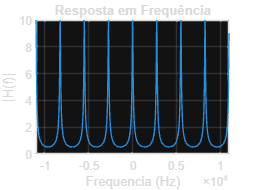

D = 8;
a = 0.9;

num = 1;
den = [1 zeros(1, D-1), -a];
figure;
[H,f]=respfreq(num,den,fa);

    e)

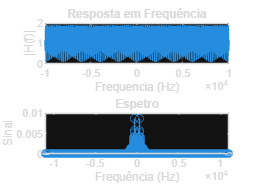

atraso = 0.01; % 10 milisegundos
D = round(atraso*fa);
den = 1;
num = [1 zeros(1, D-1), -a];
figure;
subplot(2,1,1);
[H,f]=respfreq(num,den,fa);
xlim([-1e4 1e4]);

y = filter(num,den,x);
subplot(2,1,2);

[Y, f1] = espetro(y,1/fa);